dataPath = 'acc\';        % 路径
dataDir = dir([dataPath '*.txt']); 

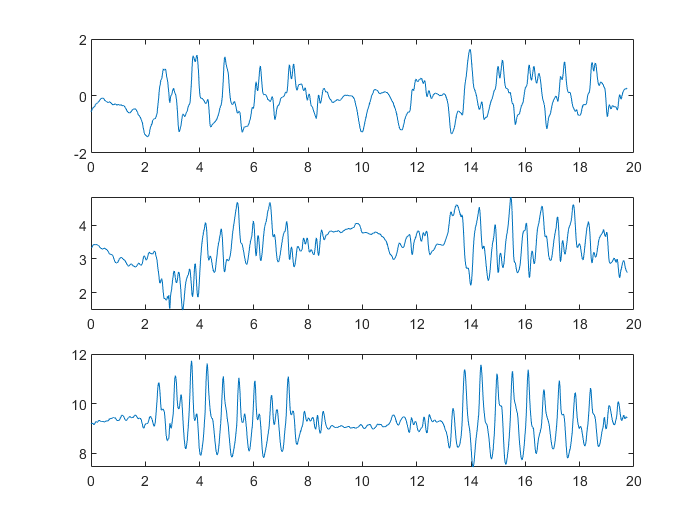

data = importdata([dataPath dataDir(3).name]);
base_time = data(1,4);
t = 0.001*(data(:,4)' - base_time);
ax = data(:,1)';
ay = data(:,2)';
az = data(:,3)';

figure(1)
subplot(3,1,1);
plot(t, ax);
subplot(3,1,2);
plot(t, ay);
subplot(3,1,3);
plot(t, az);

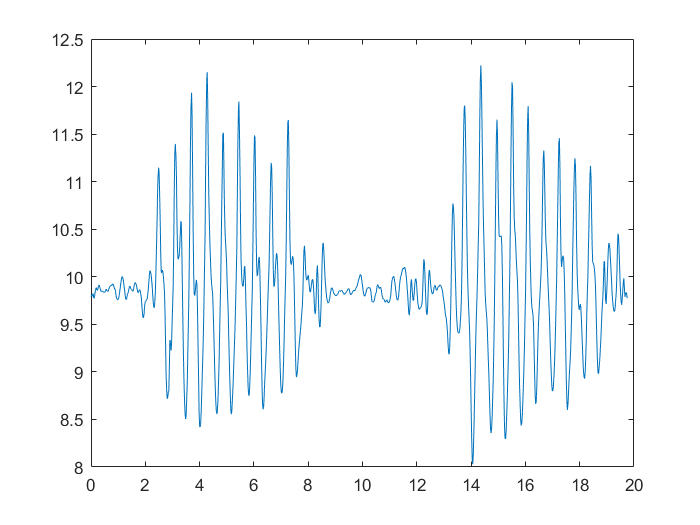

a = ax.*ax + ay.*ay + az.*az;
a = power(a, 0.5);
figure(5)
plot(t,a)

b = a(773:827)';
c = sum(b.*b)

c = 5.4420e+03

c = power(c, 0.5)

c = 73.7702

% N = 70
% b = a(773+N:827+N-24)';
% c = sum(b.*b)
% c = power(c, 0.5)

std(b)

ans = 1.0413

b(18:55) = 9;
std(b)

ans = 0.8963

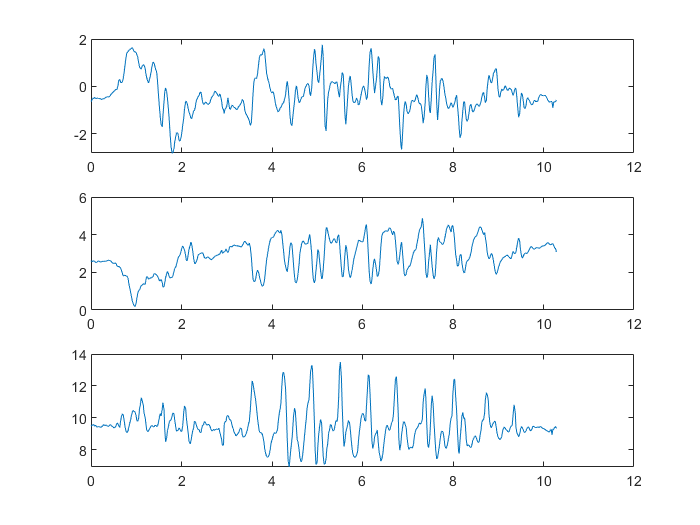

% unfilted
data = importdata([dataPath dataDir(1).name]);
base_time = data(1,4);
t = 0.001*(data(:,4)' - base_time);
ax = data(:,1)';
ay = data(:,2)';
az = data(:,3)';

figure(3)
subplot(3,1,1);
plot(t, ax);
subplot(3,1,2);
plot(t, ay);
subplot(3,1,3);
plot(t, az);

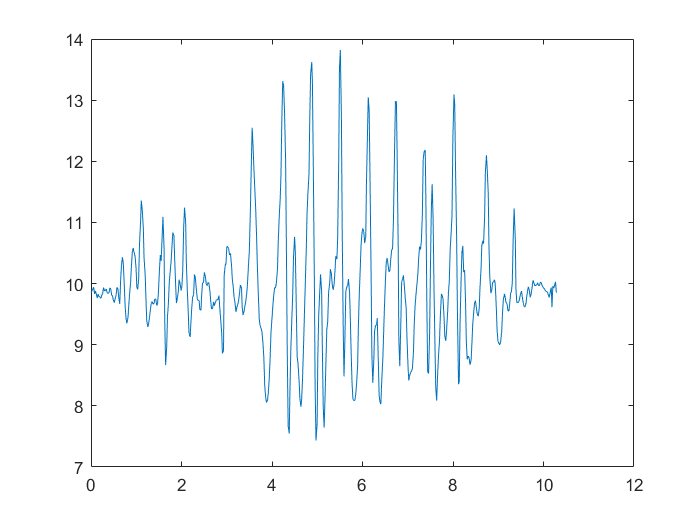

a = ax.*ax + ay.*ay + az.*az;
a = power(a, 0.5);
figure(4)
plot(t,a)